# **Intelligent Algorithm For Lung Cancer Diagnosis using extracted features**

## RAW Lung CT-scan Images

You will find the [DataSet](https://data.mendeley.com/preview/p2r42nm2ty?a=3e784ba3-9b3e-43d7-936c-11c129766e88) here.

close all; clear; clc;
% Cancerous raw images
Dataset1=imageDatastore('path where you stored them','LabelSource','foldernames','IncludeSubfolders',true);
% Non-Cancerous raw images
Dataset2=imageDatastore('path where you stored them','LabelSource','foldernames','IncludeSubfolders',true);
Img1=char(Dataset1.Files());
Img2=char(Dataset2.Files());

## Image Preprocessing

ct=0;
for e=1:length(Img1)
    ct=ct+1;
    M1=imread(Img1(e,:));
    % Under different circumstances we might need to resize the images
    % Resize the image to be 50% of its original size
    resized_img1=imresize(M1,[512,512]);
    % Apply a median filter with a 3x3 neighborhood
    denoised_img1=medfilt3(resized_img1,[3 3 3]);
    imwrite(denoised_img1,"path where you want to store them" +"CT"+string(ct)+"_1.jpg");
end
for e=1:length(Img2)
    ct=ct+1;
    M2=imread(Img2(e,:));
    % Under different circumstances we might need to resize the images 
    % Resize the image to be 50% of its original size
    resized_img2=imresize(M2,[512,512]);
    % Apply a median filter with a 3x3 neighborhood
    denoised_img2=medfilt3(resized_img2,[3 3 3]);
    imwrite(denoised_img2,"path where you want to store them"+"CT"+string(ct)+"_0.jpg");
end

## **Image Segmentation**

% Read in the image
Dataset3=imageDatastore('path where you stored them','LabelSource','foldernames','IncludeSubfolders',true);
Img3=char(Dataset3.Files());
for e=1:length(Img3)
    M3=imread(Img3(e,:));
    s=string(erase(Img3(e,:),{['path where you stored them'],' '}));
    % Convert the image to grayscale
    gray_img=im2gray(M3);
    % Compute the gradient of the grayscale image
    [gradMag,gradDir]=imgradient(gray_img);
    % Apply morphological operations, such as dilation and erosion, to the gradient image
    % to enhance the boundaries between regions
    se=strel('disk',5);
    gradMag=imdilate(gradMag,se);
    gradMag=imerode(gradMag,se);
    ws=im2double(watershed(gradMag));
    imwrite(ws,"path where you stored them"+s);
end

## **Image Feature Extraction / Build A Numerical Dataset**

Dataset4=imageDatastore('path where you stored them','LabelSource','foldernames','IncludeSubfolders',true);
Img4=char(Dataset4.Files());
MainDataSet=[];
for e=1:length(Img4)
    M4=imread(Img4(e,:));
    d=erase(Img4(e,:),{['path where you stored them'],'.jpg',' '});

### The Gabor Features

    % Convert the image to grayscale
    Igray=im2gray(M4);
    % Define the Gabor filter parameters
    wavelength=4; orientation=30;
    g=gabor(wavelength,orientation);
    % Apply the Gabor filter to the image
    Igabor=imgaborfilt(Igray,g);
    % Compute the Gabor features
    gaborfeatures=reshape(abs(Igabor),1,[]);

### The Sobel Features

    % Apply the Sobel filter to the image
    Isobel=edge(Igray,'Sobel');
    % Compute the Sobel features
    Sobelfeatures=reshape(double(Isobel),1,[]);

### The Scharr Features

    % Apply the Scharr filter to the image
    horizontalFilter=[3 0 -3; 10 0 -10; 3 0 -3];
    verticalFilter=[3 10 3; 0 0 0; -3 -10 -3];
    horizontalEdges=imfilter(double(Igray),horizontalFilter);
    verticalEdges=imfilter(double(horizontalEdges),verticalFilter);
    scaledImage=abs(verticalEdges)/max(abs(verticalEdges(:)));
    scaledImage=reshape(scaledImage,1,[]);

### The Prewitt Features

    % Apply the Prewitt filter to the image
    Iprewitt=edge(Igray,'Prewitt');
    % Compute the Prewitt features
    Prewittfeatures=reshape(double(Iprewitt),1,[]);

### The Gaussian Features

    % Apply the Gaussian filter to the image
    Igaussian=imgaussfilt(Igray,3);
    % Compute the Gaussian features
    Gaussianfeatures=reshape(double(Igaussian),1,[]);

### The Roberts Features

    % Apply the Roberts edge filter to the image
    Iroberts=edge(Igray,'Roberts');
    % Compute the Roberts features
    Robertsfeatures=reshape(double(Iroberts),1,[]);
    newfeatures=[gaborfeatures Sobelfeatures scaledImage Prewittfeatures Gaussianfeatures Robertsfeatures str2double(string(d(end)))];
    MainDataSet=[MainDataSet;newfeatures];
end
% store MainDataSet matrix
save('path where you want to store it\MainDataSet.mat','MainDataSet','-v7.3');

## **Dimensional Reduction**

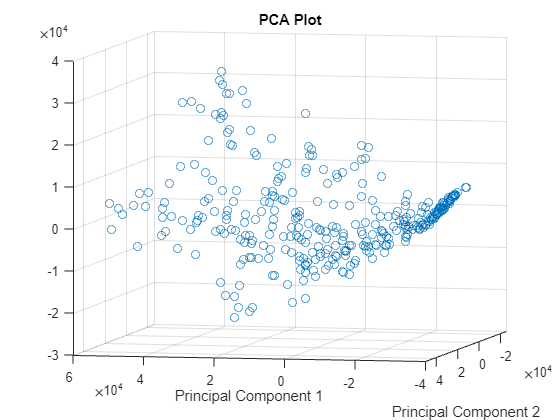

load('path where you stored it\MainDataSet');
X=MainDataSet(:,1:end-1);
Y=MainDataSet(:,end);

% Perform PCA on the dataset
[coeff,score,latent]=pca(X);
% Plot the results
figure;
scatter3(score(:,1),score(:,2),score(:,3)); % Scatter plot
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA Plot');
view([-167 6])

## **Feature Selection/Classification**

% fitcensemble returns the trained classification ensemble model object (Mdl) on score(1:264,:), (Dimensionally-reduced Dataset)
% that contains the results of boosting 100 classification trees
mdl1=fitcensemble(score(1:264,:),Y(1:264),'Method','GentleBoost','NumLearningCycles',100);
mdl2=fitcensemble(score(1:264,:),Y(1:264),'Method','AdaBoostM1','NumLearningCycles',100);
mdl3=fitcensemble(score(1:264,:),Y(1:264),'Method','LogitBoost','NumLearningCycles',100);
mdl4=fitcensemble(score(1:264,:),Y(1:264),'Method','RobustBoost','NumLearningCycles',100);
mdl5=fitcensemble(score(1:264,:),Y(1:264),'Method','LPBoost','NumLearningCycles',100);

% Evaluate the performance of the classifier on the testing data: score(265:end,:)
Y_pred1=predict(mdl1,score(265:end,:));
accuracy1=sum(Y_pred1==Y(265:end,:))/numel(Y(265:end,:));
Y_pred2=predict(mdl2,score(265:end,:));
accuracy2=sum(Y_pred2==Y(265:end,:))/numel(Y(265:end,:));
Y_pred3=predict(mdl3,score(265:end,:));
accuracy3=sum(Y_pred3==Y(265:end,:))/numel(Y(265:end,:));
Y_pred4=predict(mdl4,score(265:end,:));
accuracy4=sum(Y_pred4==Y(265:end,:))/numel(Y(265:end,:));
Y_pred5=predict(mdl5,score(265:end,:));
accuracy5=sum(Y_pred5==Y(265:end,:))/numel(Y(265:end,:));

% Display the results
disp(['Accuracy: ' num2str(accuracy1)]);

Accuracy: 0.96


disp(['Accuracy: ' num2str(accuracy2)]);

Accuracy: 1


disp(['Accuracy: ' num2str(accuracy3)]);

Accuracy: 0.99


disp(['Accuracy: ' num2str(accuracy4)]);

Accuracy: 0.98


disp(['Accuracy: ' num2str(accuracy5)]);

Accuracy: 1


% fitcensemble returns the trained classification ensemble model object (MdlX) on X(1:264,:)
% that contains the results of boosting 100 classification trees
mdlX1=fitcensemble(X(1:264,:),Y(1:264),'Method','GentleBoost','NumLearningCycles',100);
mdlX2=fitcensemble(X(1:264,:),Y(1:264),'Method','AdaBoostM1','NumLearningCycles',100);
mdlX3=fitcensemble(X(1:264,:),Y(1:264),'Method','LogitBoost','NumLearningCycles',100);
mdlX4=fitcensemble(X(1:264,:),Y(1:264),'Method','RobustBoost','NumLearningCycles',100);
mdlX5=fitcensemble(X(1:264,:),Y(1:264),'Method','LPBoost','NumLearningCycles',100);

% Evaluate the performance of the classifier on the testing data: X(265:end,:)
Y_predX1=predict(mdlX1,X(265:end,:)); 
accuracyX1=sum(Y_predX1==Y(265:end,:))/numel(Y(265:end,:));
Y_predX2=predict(mdlX2,X(265:end,:)); 
accuracyX2=sum(Y_predX2==Y(265:end,:))/numel(Y(265:end,:));
Y_predX3=predict(mdlX3,X(265:end,:)); 
accuracyX3=sum(Y_predX3==Y(265:end,:))/numel(Y(265:end,:));
Y_predX4=predict(mdlX4,X(265:end,:)); 
accuracyX4=sum(Y_predX4==Y(265:end,:))/numel(Y(265:end,:));
Y_predX5=predict(mdlX5,X(265:end,:)); 
accuracyX5=sum(Y_predX5==Y(265:end,:))/numel(Y(265:end,:));

% Display the results
disp(['Accuracy: ' num2str(accuracyX1)]);

Accuracy: 0.98


disp(['Accuracy: ' num2str(accuracyX2)]);

Accuracy: 0.74


disp(['Accuracy: ' num2str(accuracyX3)]);

Accuracy: 0.98


disp(['Accuracy: ' num2str(accuracyX4)]);

Accuracy: 0.98


disp(['Accuracy: ' num2str(accuracyX5)]);

Accuracy: 0.74
